clear;
%run("data/c3x7_s1602_l48.m");
%run("data/c3x7_s1794_l290.m");
%run("data/c3x7_s1914_l275.m")
fileName = "data/c3x7_s1602_l48.m";
run(fileName);

A = inv(T22)*O12'*inv(T11)*O12;
B = inv(T11)*O12*inv(T22)*O12';
[W1, D] = eig(A)

W1 =    0.2034 + 0.0510i  -0.1567 - 0.4620i   0.0840 + 0.0308i
   0.9594 + 0.0000i   0.1195 - 0.2724i   0.0359 - 0.1691i
   0.0247 + 0.1872i   0.8207 + 0.0000i   0.9809 + 0.0000i


D =    0.2075 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.8860 - 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.7888 - 0.0000i


[W2, D2] = eig(B)

W2 =    0.2999 + 0.0055i  -0.3439 - 0.2937i   0.0832 + 0.0673i
   0.9415 + 0.0000i   0.1539 + 0.0967i   0.0316 - 0.1790i
   0.1525 + 0.0171i   0.8732 + 0.0000i   0.9775 + 0.0000i


D2 =    0.2075 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.8860 - 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.7888 - 0.0000i



CoherencePoints = complex(zeros(1, 3));
for k = 1:3
    w1 = W1(:, k);
    w2 = (W2(:, k));
    phi = angle(w1'*w2);
    %w1 = w1*exp(-j*phi);
    num = w1' * O12 * w2;
    %Calculate denomerator
    denom = sqrt((w1' * T11 * w1) * (w2' * T22 * w2));
    point = num/denom
    CoherencePoints(k) = point;
end

point = -0.0015 - 0.1524i

point = -0.4893 - 0.7410i

point = -0.0643 - 0.8193i

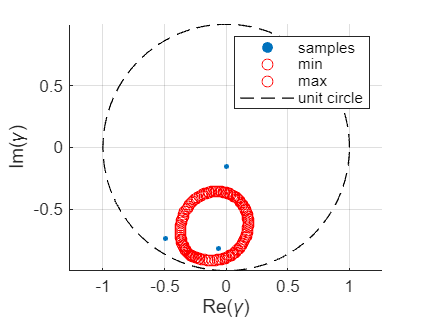


boundary_N = 60;
boundary_vals = BoundaryScan(fileName, boundary_N);

figure('Name','Coherence points','NumberTitle','off');
hold on;  % keep all plots in the same figure
axis equal; grid on;

% scatter plot of your samples
scatter(real(CoherencePoints), imag(CoherencePoints), 8, 'filled');

scatter(real(boundary_vals(:,1)), imag(boundary_vals(:,1)), 'ro', 'red');
scatter(real(boundary_vals(:,2)), imag(boundary_vals(:,2)), 'ro', 'red');

% draw unit circle for reference
th = linspace(0,2*pi,500);
plot(cos(th), sin(th), 'k--', 'LineWidth', 0.7);

% labels and title
xlabel('Re(\gamma)'); 
ylabel('Im(\gamma)');


% legend
legend('samples','min','max', 'unit circle');

hold off;  % optional, release hold